# KUNCI Praktikum 3 - Shift 2 Kamis

`30 September 2021`

`Nama : `**Asisten Praktikum**

`NIM  :`

## Nomor 1

Jelaskan secara singkat keunggulan metode eliminasi Gauss dengan penumpuan parsial, dibandingkan metode eliminasi Gauss biasa !

#### **Jawaban :**

Penumpuan parsial digunakan sedemikian rupa sehingga proses penumpuan selalu dilakukan oleh elemen terbesarnya. Akibatnya, pembagian dengan 0 atau *zero division* dapat dihindari.

Selain itu, benefit lain dari penggunaan penumpuan parsial adalah dapat meminimalisir galat pembulatan saat perhitungan dengan program.

## **Nomor 2**

Apakah kekonvergenan dalam metode Jacobi dan Gauss-Seidel dijamin? Apakah kekonvergenannya dipengaruhi oleh tebakan awal? Jelaskan !

#### **Jawaban :**

Tidak, karena kedua metode tersebut bisa saja tidak konvergen. Metode tersebut akan dijamin konvergen apabila matriks yang digunakan diagonal dominan tegas. 

Apabila matriksnya diagonal dominan tegas (metodenya dijamin konvergen), maka tebakan awal apapun akan menghasilkan solusi yang konvergen.

## Nomor 3

Dalam industri kimia, senyawa yang sama harus dapat digunakan dalam konsentrasi yang berbeda-beda. Untuk mendapatkan konsentrasi yang lebih rendah ataupun lebih tinggi dari suatu zat, digunakan proses ekstraksi, yaitu proses mengambil suatu ekstrat dari sebuah matriks senyawa mentah. Sistem ekstraksi bertahap tersebt berlangsung pada $n$ buah reaktor dengan ilustrasi sebagai berikut:

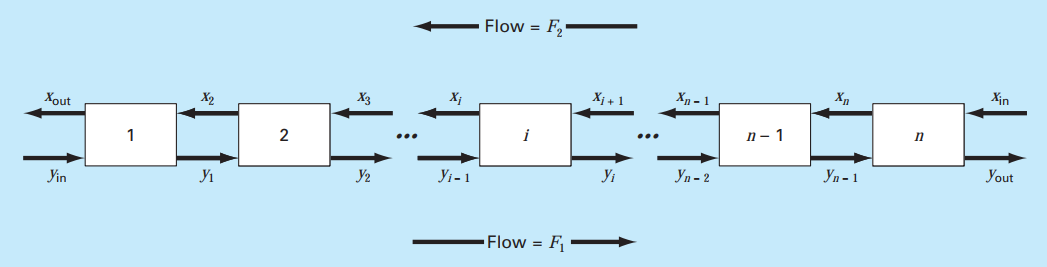

Pada sistem tersebut, aliran senyawa dengan konsentrasi $Y_{in}$ memasuki sistem dari kiri dengan laju $F_1$. Pada saat yang sama, pelarut yang memuat senyawa yang sama dengan konsentrasi $X_{in}$ memasuki sistem dari kanan dengan laju $F_2$. Dengan demikian, pada reaktor ke- $i$, persamaan keseimbangan massa diberikan oleh

### 
$$F_1 Y_{i-1} +F_2 X_{i+1} =F_1 Y_i +F_2 X_i$$


Pada setiap reaktor, sebuah kesetimbangan diasumsikan antara $X_i$ dan $Y_i$ sebagai berikut

### 
$$K=\frac{X_i }{Y_i }$$


dengan $K$disebut koefisien distribusi. 

### 3A.

Diketahui bahwa dengan memanfaatkan dua persamaan diatas, kita dapat peroleh suatu hubungan :

### 
$$Y_{i-1}-\left(1+\frac{F_2}{F_1}K \right) Y_i + \left(\frac{F_2}{F_1} K \right)Y_{i+1}=0\;\; (*)$$
   

Misalkan terdapat sistem ekstraksi dengan $n$ reaktor dan suatu matriks  $Y=[Y_1, Y_2, ..., Y_{n}]^T$. Tuliskan sistem persamaan linear (SPL) $MY=B$ yang diperoleh dari persamaan ($*$). (Gunakan $y_0=y_{in}$ )

#### **Jawaban (Dapat diketik/difoto) :**

Perhatikan bahwa untuk $i=1$ sampai $i=n$, kita peroleh sistem persamaan berikut


$$Y_{0}-\left(1+\frac{F_2}{F_1}K \right) Y_1 + \left(\frac{F_2}{F_1} K \right)Y_{2}=0$$



$$Y_{1}-\left(1+\frac{F_2}{F_1}K \right) Y_2 + \left(\frac{F_2}{F_1} K \right)Y_{3}=0$$



$$Y_{2}-\left(1+\frac{F_2}{F_1}K \right) Y_3 + \left(\frac{F_2}{F_1} K \right)Y_{4}=0$$



$$\vdots$$



$$Y_{n-2}-\left(1+\frac{F_2}{F_1}K \right) Y_{n-1} + \left(\frac{F_2}{F_1} K \right)Y_{n}=0$$



$$Y_{n-1}-\left(1+\frac{F_2}{F_1}K \right) Y_n + \left(\frac{F_2}{F_1} K \right)Y_{n+1}=0$$


Perhatikan bahwa terdapat suku $Y_0$ dan $Y_{n+1}$. Dari diagram, kita punya $Y_0=Y_{in}$, sehingga diperoleh 


$$-\left(1+\frac{F_2}{F_1}K \right) Y_1 + \left(\frac{F_2}{F_1} K \right)Y_{2}=-Y_{0}=-Y_{in}$$


Untuk $Y_{n+1}$, perhatikan bahwa kita punya hubungan $Y_{n+1}=X_{n+1}/K$ dimana $X_{n+1}=X_{in}$, jadi diperoleh $Y_{n+1}=X_{in}/K$. Didapatkan persamaan


$$Y_{n-1}-\left(1+\frac{F_2}{F_1}K \right) Y_n  =-\left(\frac{F_2}{F_1} K \right)X_{in}/K=-\left(\frac{F_2}{F_1} X_{in} \right)$$


Jadi, diperoleh sistem persamaan linear 


$$-\left(1+\frac{F_2}{F_1}K \right) Y_1 + \left(\frac{F_2}{F_1} K \right)Y_{2}=-Y_{in}$$



$$Y_{1}-\left(1+\frac{F_2}{F_1}K \right) Y_2 + \left(\frac{F_2}{F_1} K \right)Y_{3}=0$$



$$\vdots$$



$$Y_{n-2}-\left(1+\frac{F_2}{F_1}K \right) Y_{n-1} + \left(\frac{F_2}{F_1} K \right)Y_{n}=0$$



$$Y_{n-1}-\left(1+\frac{F_2}{F_1}K \right) Y_n  =-\left(\frac{F_2}{F_1} X_{in} \right)$$


yang dapat dituliskan dalam bentuk matriks sebagai $MY=B$ dengan 


$$M=$$

$$\left\lbrack \begin{array}{ccccccc}
-\left(1+\frac{F_2 }{F_1 }K\right) & \frac{F_2 }{F_1 }K & 0 & 0 & 0 & \cdots  & 0\\
1 & -\left(1+\frac{F_2 }{F_1 }K\right) & \frac{F_2 }{F_1 }K & 0 & 0 & \cdots  & 0\\
0 & 1 & -\left(1+\frac{F_2 }{F_1 }K\right) & \frac{F_2 }{F_1 }K & 0 & \cdots  & 0\\
0 & 0 & 1 & -\left(1+\frac{F_2 }{F_1 }K\right) & \frac{F_2 }{F_1 }K & \cdots  & 0\\
0 & 0 & 0 & \ddots  & \ddots  & \ddots  & 0\\
0 & 0 & 0 & 0 & 1 & -\left(1+\frac{F_2 }{F_1 }K\right) & \frac{F_2 }{F_1 }K\\
0 & 0 & 0 & 0 & 0 & 1 & -\left(1+\frac{F_2 }{F_1 }K\right)
\end{array}\right\rbrack$$


$Y=[Y_1, Y_2, ..., Y_{n}]^T$, dan


$$B=$$

$$\left\lbrack \begin{array}{c}
-Y_{\mathrm{in}} \\
0\\
\vdots \\
0\\
-\frac{F_2 }{F_1 }X_{\mathrm{in}} 
\end{array}\right\rbrack$$


### 3B

Buatkan algoritma `adukan.m` yang menerima input berupa $F_1$, $Y_{in}$, $F_2$, $X_{in}$, dan $K$, serta $n$ dan mengeluarkan input berupa konsentrasi senyawa yang dikeluarkan dari masing-masing reaktor, secara khusus $Y=\left\lbrack Y_1 ,\ldotp \ldotp \ldotp ,Y_{\mathrm{out}} \right\rbrack$. Dalam pembuatan algoritma ini, **anda dilarang menggunakan teknik penumpuan.**

**Tips:**

- Manfaatkan hubungan $X_i$ dan $Y_i$ melalui $K$.

- Perhatikan bentuk matriks yang anda peroleh di bagian 3A. Matriks jenis apakah itu?

- Perhatikan diagram dengan baik. Ingat $y_0=y_{in}$ dan $y_{out}=y_n$.

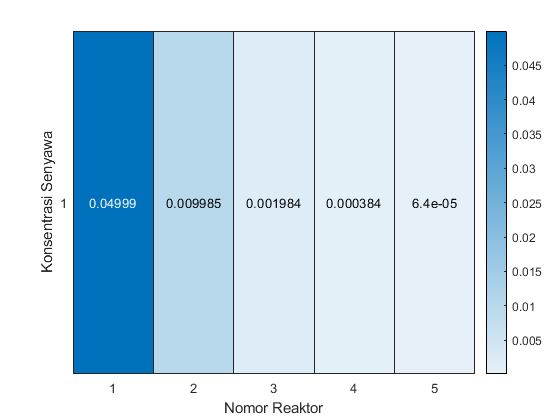

% Cek jawaban disini
clear all;clc;
format long
F_1 = 400;
F_2 = 400;
Y_in = 0.25;
X_in = 0;
K = 5;
n = 5;

h = heatmap(adukan(F_1, Y_in, F_2, X_in, K, n));
h.XLabel ='Nomor Reaktor';
h.YLabel = 'Konsentrasi Senyawa';

## Soal Bonus

### 3C

Tuliskan penurunan rumus untuk persamaan $(*)$. Gunakan fakta bahwa $F_1 Y_{i-1} +F_2 X_{i+1} =F_1 Y_i +F_2 X_i$ dan $K=\frac{X_i }{Y_i }$.

**Jawaban :**

Kita punya $X_{i+1}=KY_{i+1}$ dan $X_i=KY_i$. Diperoleh


$$F_1 Y_{i-1} + F_2KY_{i+1}=F_1Y_i + F_2KY_i$$


Bagi kedua ruas dengan $F_1$ , didapatkan


$$Y_{i-1}+\frac{F_2}{F_1}KY_{i+1} =Y_i + \frac{F_2}{F_1}KY_i$$



$$\Longrightarrow Y_{i-1} -\left(1+\frac{F_2}{F_1}K \right)Y_i + \frac{F_2}{F_1}KY_{i+1}=0 \;\; (*)$$
